# E12

## 1. Detecció de cares amb nasos

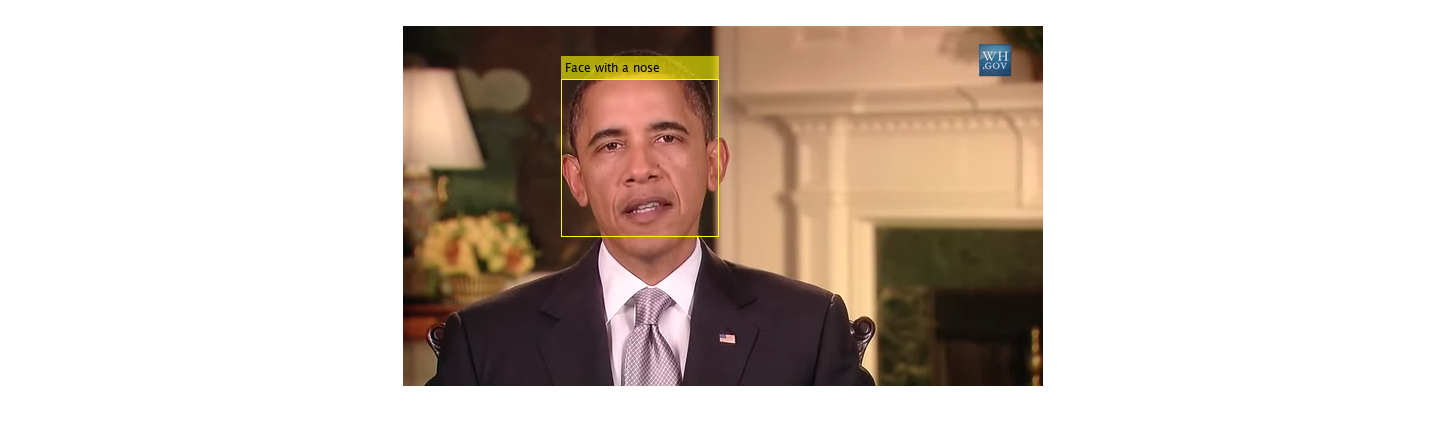

DetectorFace = vision.CascadeObjectDetector('FrontalFaceCART'); 
DetectorNose = vision.CascadeObjectDetector('Nose'); 

% Llegim el video 
VideoReader = VideoReader('obama.webm'); 

VideoReader.CurrentTime = 2; 

while hasFrame(VideoReader) 
    VideoFrame = readFrame(VideoReader); 

    % Detecció Face 
    bboxesFace = step(DetectorFace, VideoFrame);
    
    if (size(bboxesFace, 1) > 0) % Detecció Nose 

        rect = bboxesFace(1, :); 
        VideoFrameFace = imcrop(VideoFrame, rect); 
        bboxesNose = step(DetectorNose, VideoFrameFace); 

        if (size(bboxesNose, 1) > 0) 
            VideoFrame = insertObjectAnnotation(VideoFrame,'rectangle',bboxesFace,'Face with a nose'); 
        end 
    end 

    imshow(VideoFrame); 
    drawnow 
end

## 2. Tracking per SIFT

Trobem la primera cara AMB NAS

DetectorFace = vision.CascadeObjectDetector('FrontalFaceCART');
DetectorNose = vision.CascadeObjectDetector('Nose');

VideoReader = VideoReader('obama.webm');

VideoReader.CurrentTime = 2;

found = false;

while not(found)
    VideoFrame = readFrame(VideoReader);

    % Detecció Face
    bboxesFace = step(DetectorFace, VideoFrame);

    if (size(bboxesFace, 1) > 0)
        % Detecció Nose
        rect = bboxesFace(1, :);
        VideoFrameFace = imcrop(VideoFrame, rect);
        bboxesNose = step(DetectorNose, VideoFrameFace);
   
        if (size(bboxesNose, 1) > 0)
            found = true;
            im_obj = rgb2gray(VideoFrameFace);
        end
    end
end

Ara fem tracking d'aquesta mitjançant SIFT i RANSAC

im_esc = VideoReader;

while hasFrame(VideoReader)
    
    % Llegim el frame com escena
    im_esc = rgb2gray(readFrame(VideoReader)); 
    
    % Detectem features per SIFT
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);
    
    % Filtrem pels més "forts"
    %kp_obj = selectStrongest(kp_obj, 30);
    %kp_esc = selectStrongest(kp_esc, 200);

    [feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj);
    [feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc);
    
    pairs = matchFeatures(feat_obj, feat_esc, "MatchThreshold", 10);
    
    m_kp_obj = kp_obj(pairs(:, 1), :);
    m_kp_esc = kp_esc(pairs(:, 2), :);
    
    showMatchedFeatures(im_obj, im_esc, m_kp_obj, m_kp_esc, "montage")
    drawnow;

end